### load dataset - simple contrast (dummy coding) stim Pain

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

mount_dir = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel'

con_list = dir(fullfile(mount_dir, '*/con_0009.nii'));
spm('Defaults','fMRI')
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_social/analysis/fmri/spm/univariate/model-02_CcEScA/1stLevel/sub-0003/con_0009.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 25558272 bytes
Loading image number:    64
Elapsed time is 3.445403 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 6191567  Bit rate: 22.56 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'cueXcue_P', 'cueXcue_V', 'cueXcue_C', 'cueXcue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'stimXcue_P', 'stimXcue_V', 'stimXcue_C', 'stimXcue_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C',...
    'simple_cueXcue_P', 'simple_cueXcue_V', 'simple_cueXcue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C',...
    'simple_stimXcue_P', 'simple_stimXcue_V', 'simple_stimXcue_C'};

### `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              15:35:45 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


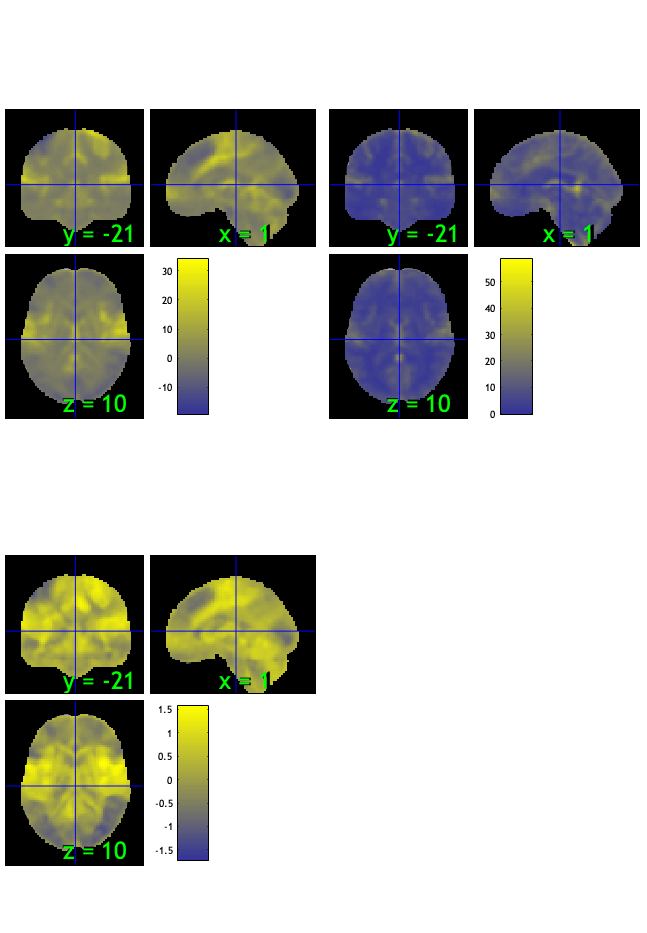

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.75%
Expected 3.20 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 24 33 35 
Uncorrected: 5 images		Cases 2 24 33 34 35 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.31%
Expected 3.20 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 17 20 33 60 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                              

SPM12: spm_check_registration (v7759)              15:36:03 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

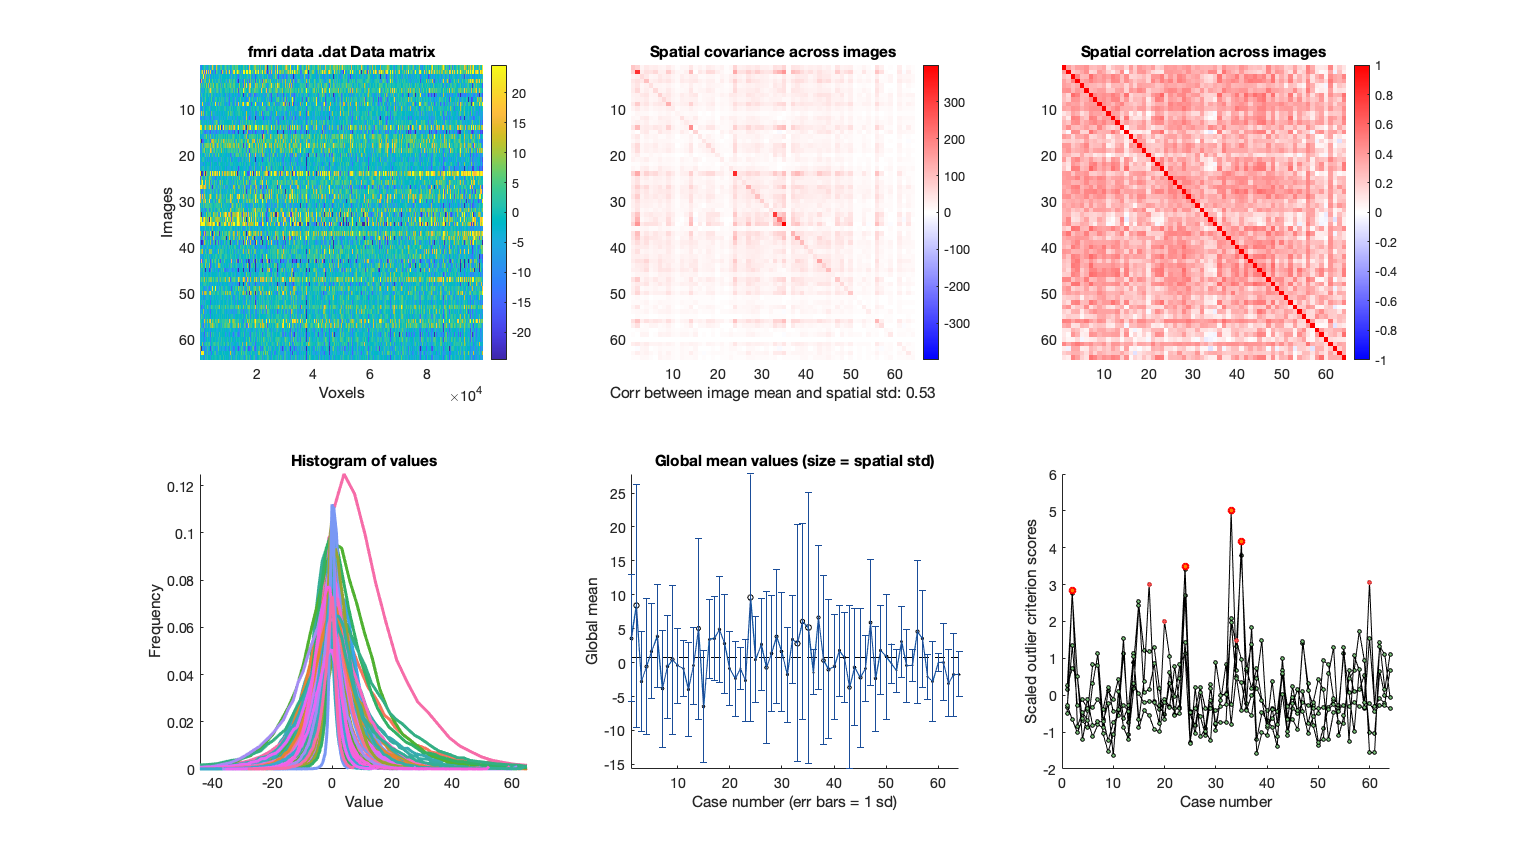

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


ans = 64×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


drawnow; snapnow

plot(con_data_obj)

### run robfit

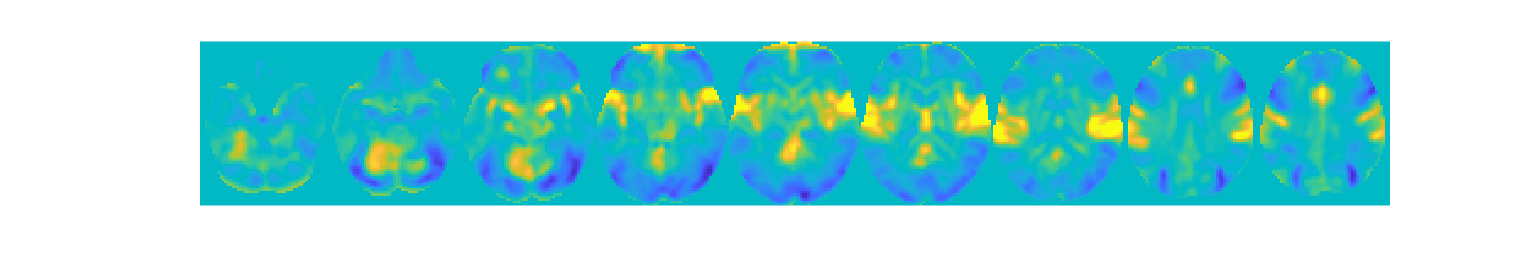

set(gcf,'Visible','on')

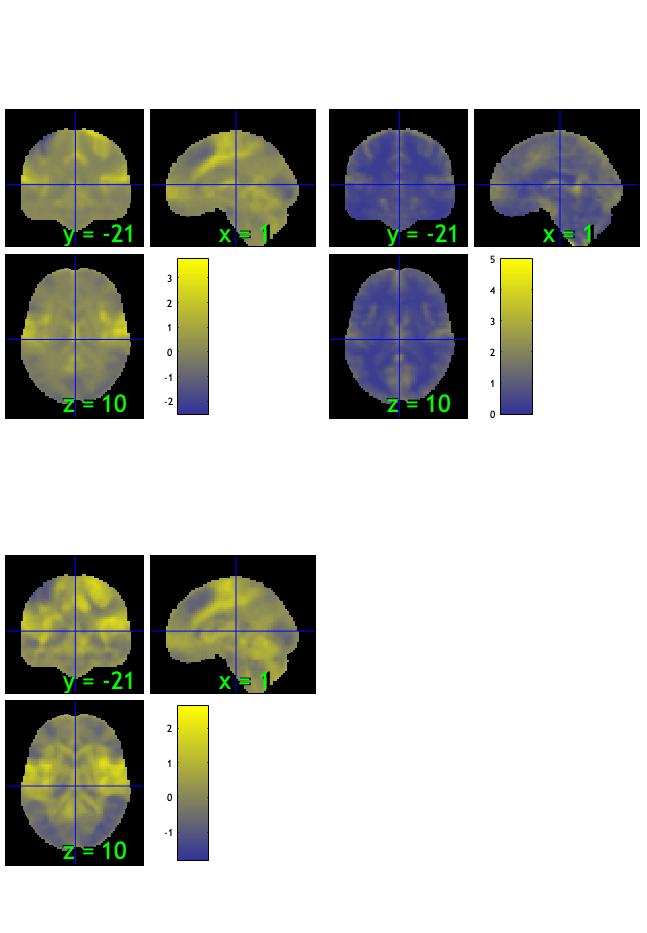

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.44%
Expected 3.20 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 2 images		Cases 55 60 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.31%
Expected 3.20 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 17 20 33 60 

Mahalanobis (cov and corr, q<0.05 corrected):
  0 images 
                               Outlier_count    Percentage
                               _______

SPM12: spm_check_registration (v7759)              15:36:30 - 27/04/2022
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

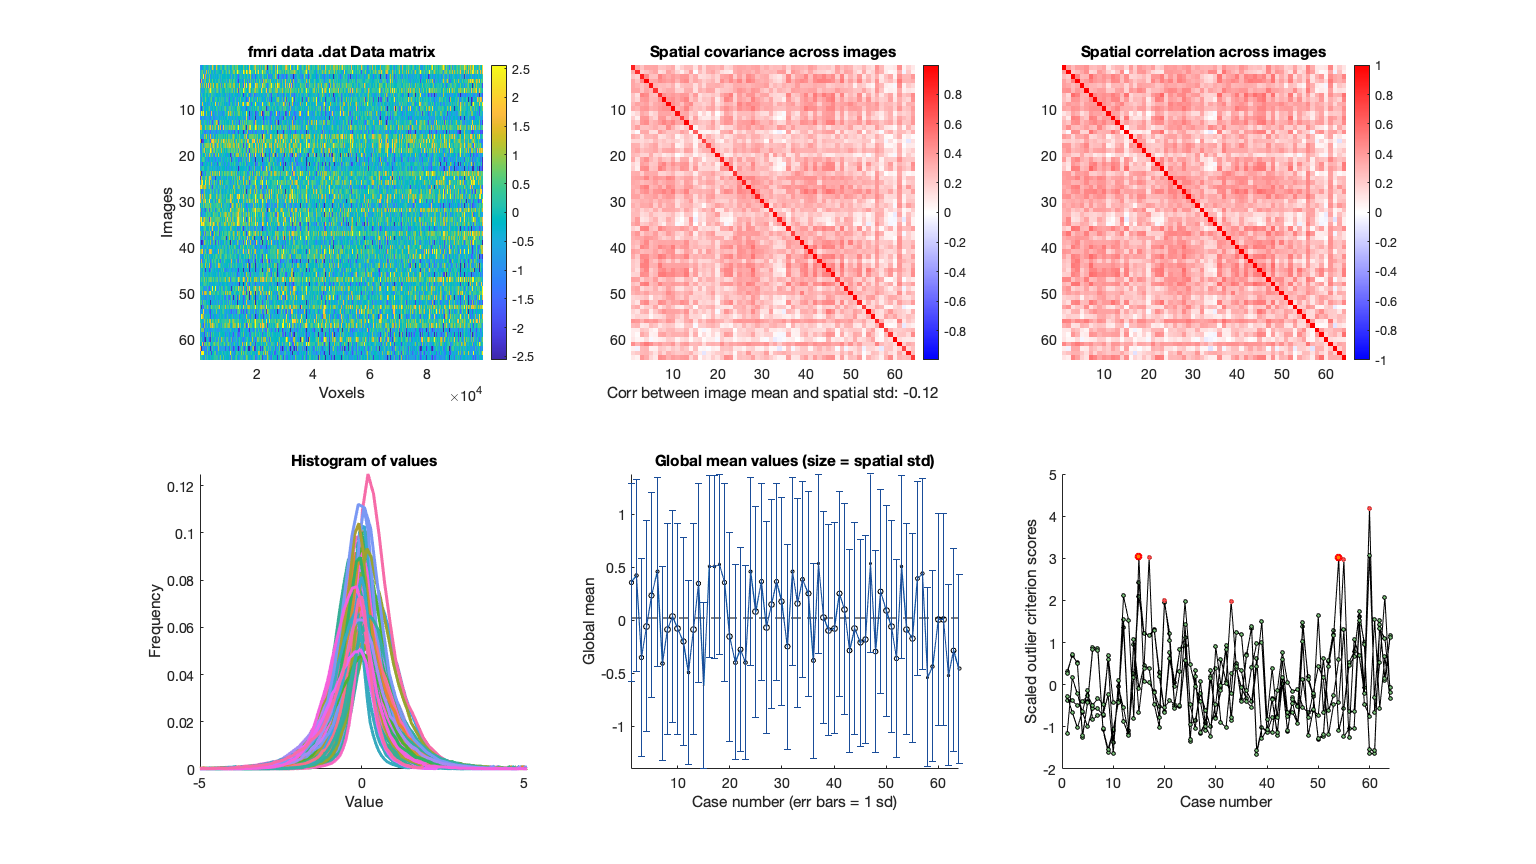

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


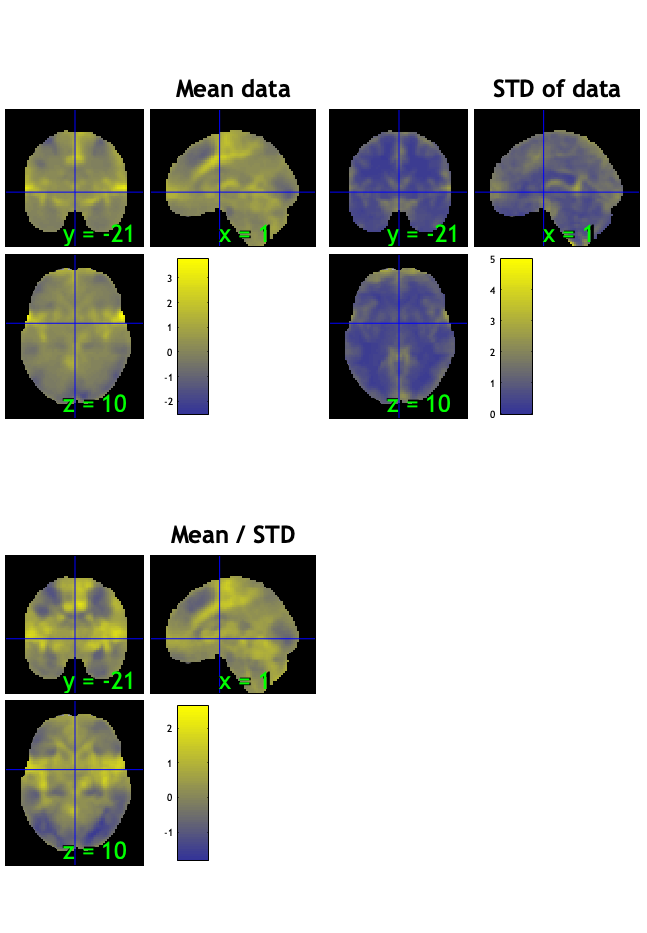

ans = 64×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


figure ('Visible', 'on');
drawnow, snapnow;
imgs2 = con_data_obj.rescale('l2norm_images');
plot(imgs2)

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


t = threshold(t, .05, 'fdr', 'k', 10);  

Image   1 FDR q < 0.050 threshold is 0.029892

Image   1
  7 contig. clusters, sizes  12 to 59252
Positive effect: 30231 voxels, min p-value: 0.00000000
Negative effect: 29427 voxels, min p-value: 0.00000000


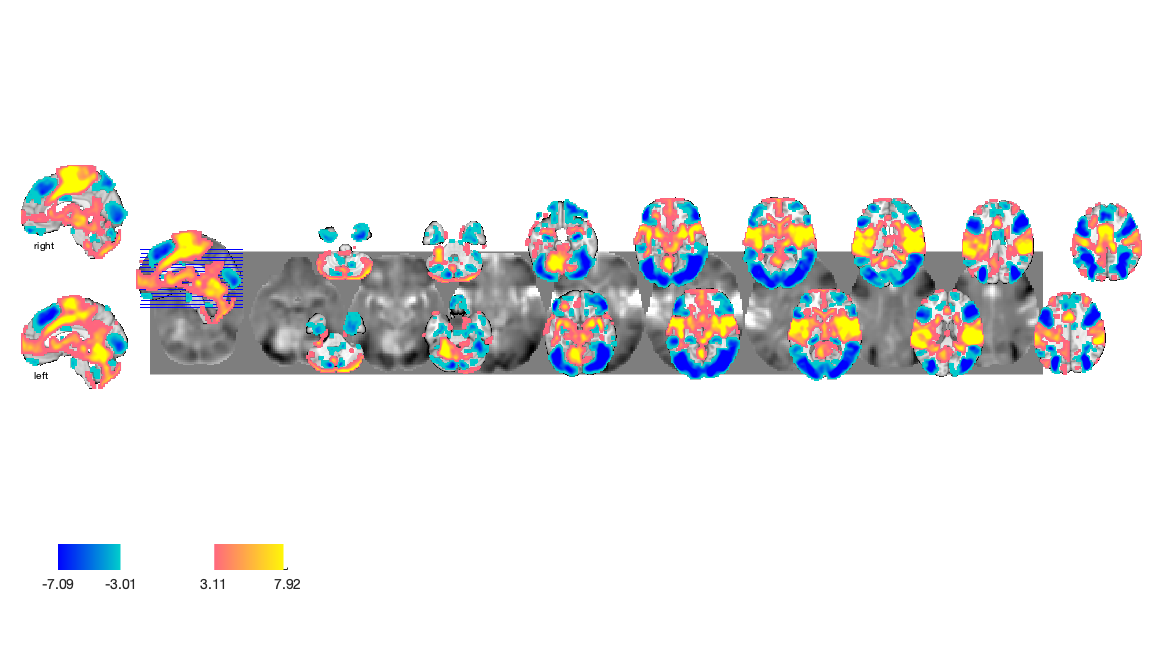

Setting up fmridisplay objects


sagittal montage: 1431 voxels displayed, 58227 not displayed on these slices


sagittal montage: 1328 voxels displayed, 58330 not displayed on these slices


sagittal montage: 1314 voxels displayed, 58344 not displayed on these slices


axial montage: 10775 voxels displayed, 48883 not displayed on these slices


axial montage: 11783 voxels displayed, 47875 not displayed on these slices


drawnow, snapnow;
   % Show regions and print a table with labeled regions:
montage(t);  drawnow, snapnow;                  % Show results on a slice display

r = region(t);                                  % Turn t-map into a region object with one element per contig region

Grouping contiguous voxels:   7 regions


table(r);                                       % Print a table of results using new region names

____________________________________________________________________________________________________________________________________________
Positive Effects


sampleto = '/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask.nii'

           Region             Volume             XYZ            maxZ       modal_label_descriptions       Perc_covered_by_label    Atlas_regions_covered    region_index
    ____________________    __________    _________________    ______    _____________________________    _____________________    _____________________    ____________

    {'Multiple regions'}    8.1538e+05      3    -20     19    7.0345    {'Cerebellum'               }              2                       281                  1      
    {'Ctx_PGs_L'       }          6184    -46    -73     35    4.9052    {'Cortex_Default_ModeA'     }             45                         1                  6      
    {'Ctx_PGs_R'       }          1136     51    -7